**Transmural analysis using fabricated data**

**data_points: 5x5**

**Slices: 2**

**Read in data from slices**

warning off
clear all
close all
clc
addpath(genpath('..'));

[data_points1, size] = parseSection('3dFab_1.txt');
[data_points2] = parseSection('3dFab_2.txt');

**Generate Fourier Coefficients**


% Determine Fourier coefficients for each data_point
fs_order = 6;
h = waitbar(0,'Generating tensors');
for data_point_num = 1:length(data_points1)
    data_point_obj1 = data_points1(data_point_num);    
    data_point_obj1 = data_point_obj1.Normalize; 
    data_point_obj1 = data_point_obj1.GenerateFourier(fs_order);
    data_point_obj1 = data_point_obj1.GenerateTensors;
    data_point_obj1 = data_point_obj1.ComputeStats;
    
    data_point_obj2 = data_points2(data_point_num);  
    data_point_obj2 = data_point_obj2.Normalize;
    data_point_obj2 = data_point_obj2.GenerateFourier(fs_order);
    data_point_obj2 = data_point_obj2.GenerateTensors;
    data_point_obj2 = data_point_obj2.ComputeStats;
    
    h = waitbar(data_point_num/length(data_points1),h);
end
close(h);


**Test data_point**

data_point_O = data_points1(1);
added_in = circshift(data_point_O.intensity_data',60)/3;
data_point_O.intensity_data  = data_point_O.intensity_data + added_in';
data_point_O = data_point_O.Normalize;
data_point_O = data_point_O.GenerateFourier(fs_order);
data_point_O = data_point_O.GenerateTensors;
data_point_O = data_point_O.ComputeStats;

**Inspect Fits**

gamma_Ffit = evalFourier(data_point_O.an, data_point_O.bn, 1, 1:360);
data_point_ST = data_point_O.ComputeCoefficientsFromTensors;
gamma_FfitRad_ST = evalFourierRad(data_point_ST.an, data_point_ST.bn, 1, (1:360)*pi/180);
gamma_FfitRad = evalFourierRad(data_point_O.an, data_point_O.bn, 1, (1:360)*pi/180);

%gamma_STFit = evalGammaST(data_point_O.D,1:360);

[theta1 theta2] = data_point_O.ComputeSymAngles;

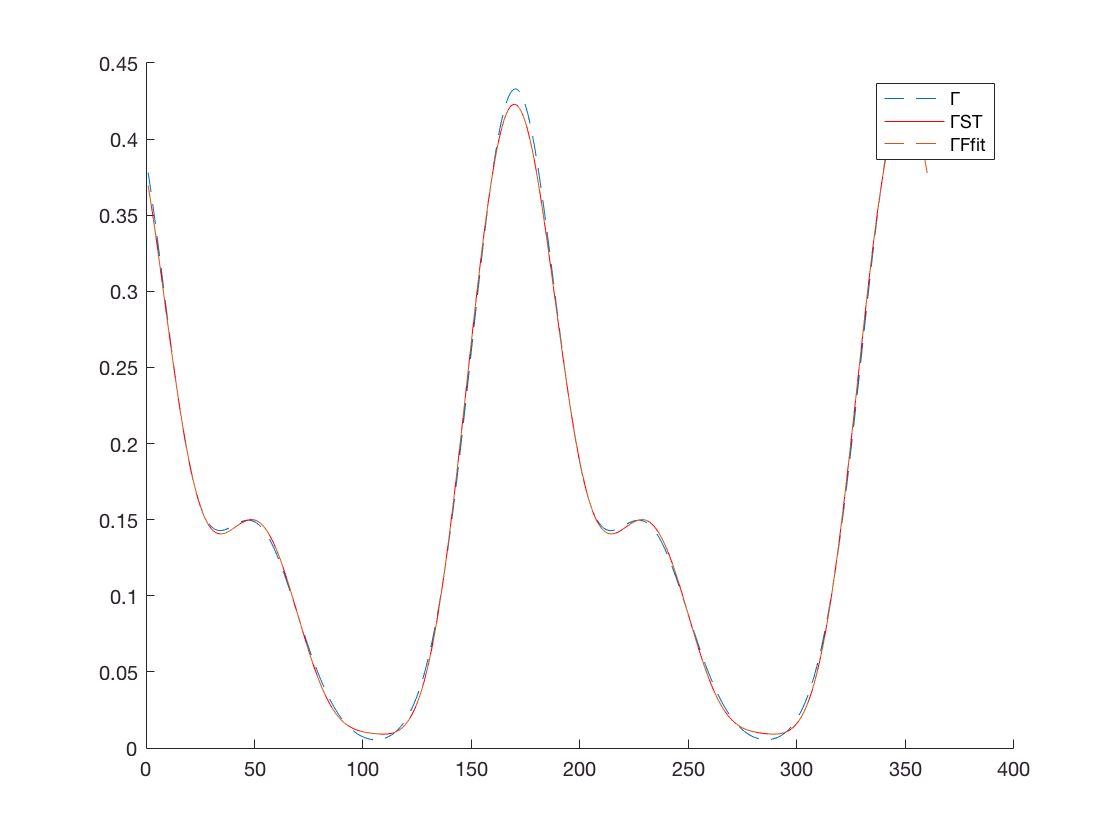

figure
hold on
plot(1:360,data_point_O.odd,'--') 
plot(1:360,gamma_FfitRad_ST,'r')
plot(1:360,gamma_FfitRad,'--')
%vline(theta1*180/pi,'b', sprintf('θI=%.2f',theta1*180/pi)); vline(theta1*180/pi+180,'b', sprintf('θI2=%.2f',theta1*180/pi+180)); 
%vline(theta2*180/pi,'r', sprintf('θII=%.2f',theta2*180/pi)); vline(theta2*180/pi+180,'r', sprintf('θII2=%.2f',theta2*180/pi+180)); 
legend('show','Γ','ΓST','ΓFfit')
hold off

**Tranformation**

Raw data is shifted according to the rotation angle.

x', y' pairs are computed from multiplication of the original position vector with the transformation matrix.

tx = 0; %% mm to the right
ty = 0;  %% mm up
theta = 45;
T = [cosd(theta) sind(theta) tx;
    -sind(theta) cosd(theta) ty; % Tranformation matrix from registration
    0 0 1];
T0 = [cosd(0) sind(0) tx;
-sind(0) cosd(0) ty; % Tranformation matrix from registration
0 0 1];

tic
data_point_R = data_point_O.ApplyTransformation2(T);
data_point_R0 = data_point_O.ApplyTransformation2(T0);
toc

Elapsed time is 7.331048 seconds.


tic
data_point_Test2 = data_point_O.ApplyTransformation2(T);
toc

Elapsed time is 0.109180 seconds.


tic
data_point_Test1 = data_point_O.ApplyTransformation(T);
toc

Elapsed time is 4.763911 seconds.


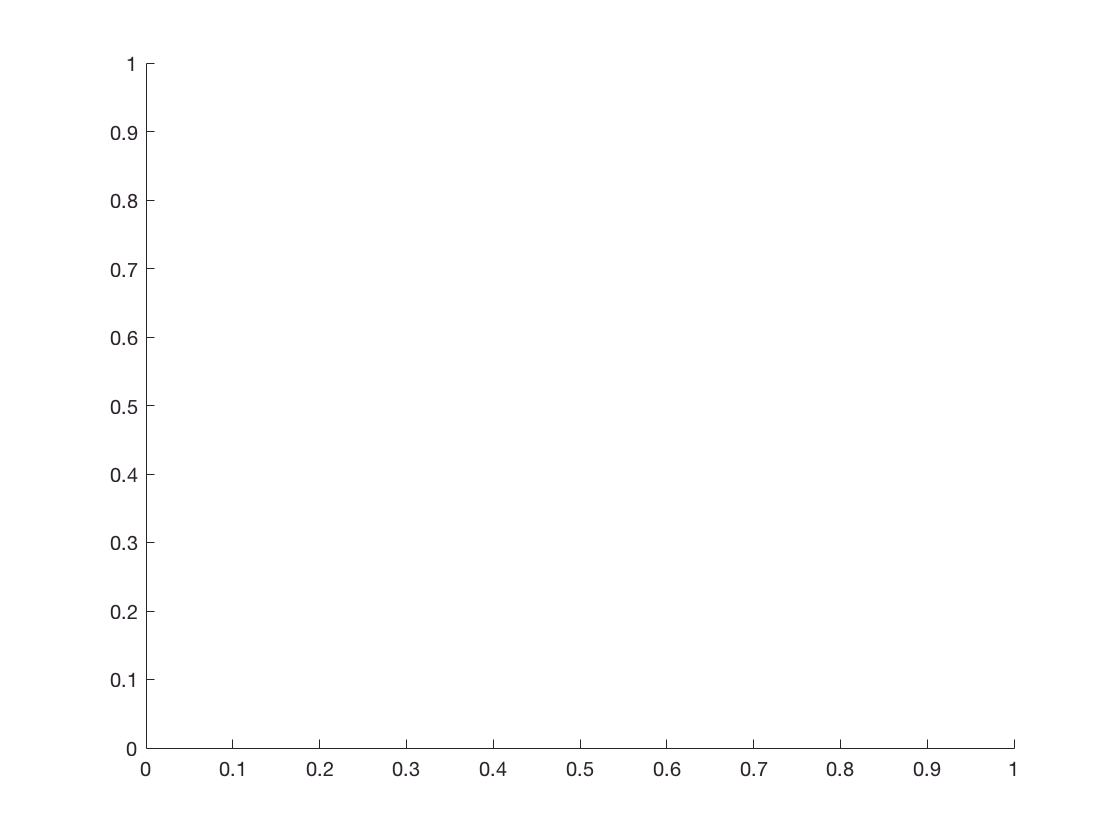


range = 1:360;
gamma_FfitT1 = evalFourier(data_point_Test1.an, data_point_Test1.bn, 1, range);
gamma_FfitT2 = evalFourier(data_point_Test2.an, data_point_Test2.bn, 1, range);
figure
hold on

plot(range, gamma_FfitO)

Undefined function or variable 'gammagamma_FfitT1_FfitO'.


plot(range, gamma_FfitT2)
legend('T1', 'T2')%, sprintf('Rotated %.2f', theta))
hold off

**Inspect post-rotation fits**

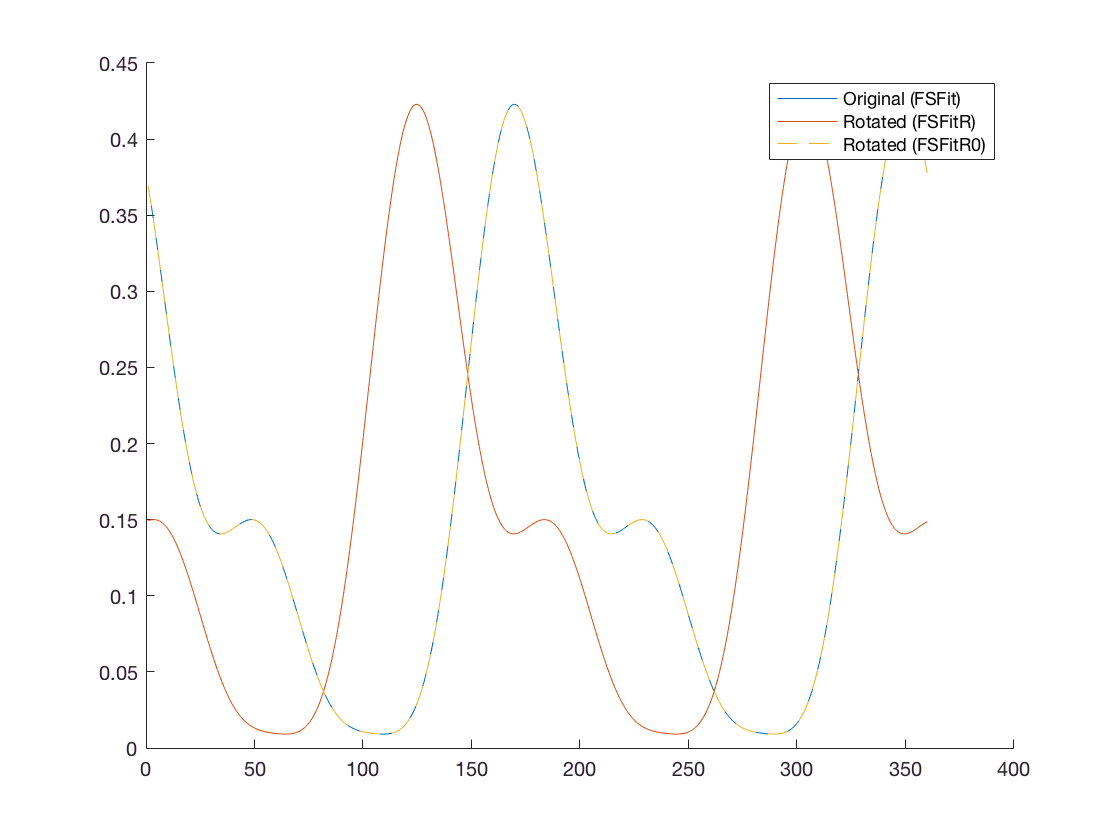

range = 1:360;
gamma_FfitO = evalFourier(data_point_O.an, data_point_O.bn, 1, range);
gamma_FfitR = evalFourier(data_point_R.an, data_point_R.bn, 1, range);
gamma_FfitR0 = evalFourier(data_point_R0.an, data_point_R0.bn, 1, range);

figure
hold on
plot(range, gamma_FfitO)
plot(range, gamma_FfitR)
plot(range, gamma_FfitR0,'--')
legend('Original (FSFit)', 'Rotated (FSFitR)','Rotated (FSFitR0)')%, sprintf('Rotated %.2f', theta))
hold off

**Interpolating**

An interpolation surface is created for each fourier coefficient, bit value and x,y point for a slice. 

The surface contains all triplets (x, y, value) where *value* is the fourier coefficient or bit values.

The result of the interpolation is the *value* of the surface at points x', y'

**Set up grid**

x = [data_points1(:).x];
y = [data_points1(:).y];
step_size =  data_points1(2).x - data_points1(1).x;
[X1, X2] = ndgrid(0.0:step_size:x(end) , 0.0:step_size:y(end));

**New data_point Position**

x_prime = .25;
y_prime = .25;

**Interpolation step to find values for each coefficient**

an_prime = [];
for i = 1:fs_order/2 % for each coeff
   f = [];
   for j = 1:prod(size) % for each data_point
       f(j) = data_points1(j).an(i);
   end

   f_r = reshape(f, [5,5]);
   F_interp = griddedInterpolant(X1, X2,f_r);
   an_prime(i) = F_interp(x_prime, y_prime);
end

bn_prime = [];
for i = 1:(fs_order/2) % for each coeff
   f = [];
   for j = 1:prod(size) % for each data_point
       f(j) = data_points1(j).bn(i);
   end

   f_r = reshape(f, [5,5]);
   F_interp = griddedInterpolant(X1, X2,f_r);
   bn_prime(i) = F_interp(x_prime, y_prime);
end

d_int = data_point;
d_int.an = an_prime;
d_int.bn = bn_prime;
d_int = d_int.GenerateTensors;
d_int.odf = evalFourier(an_prime, bn_prime, 1, 1:360);
d_int = d_int.ComputeStatsODF;

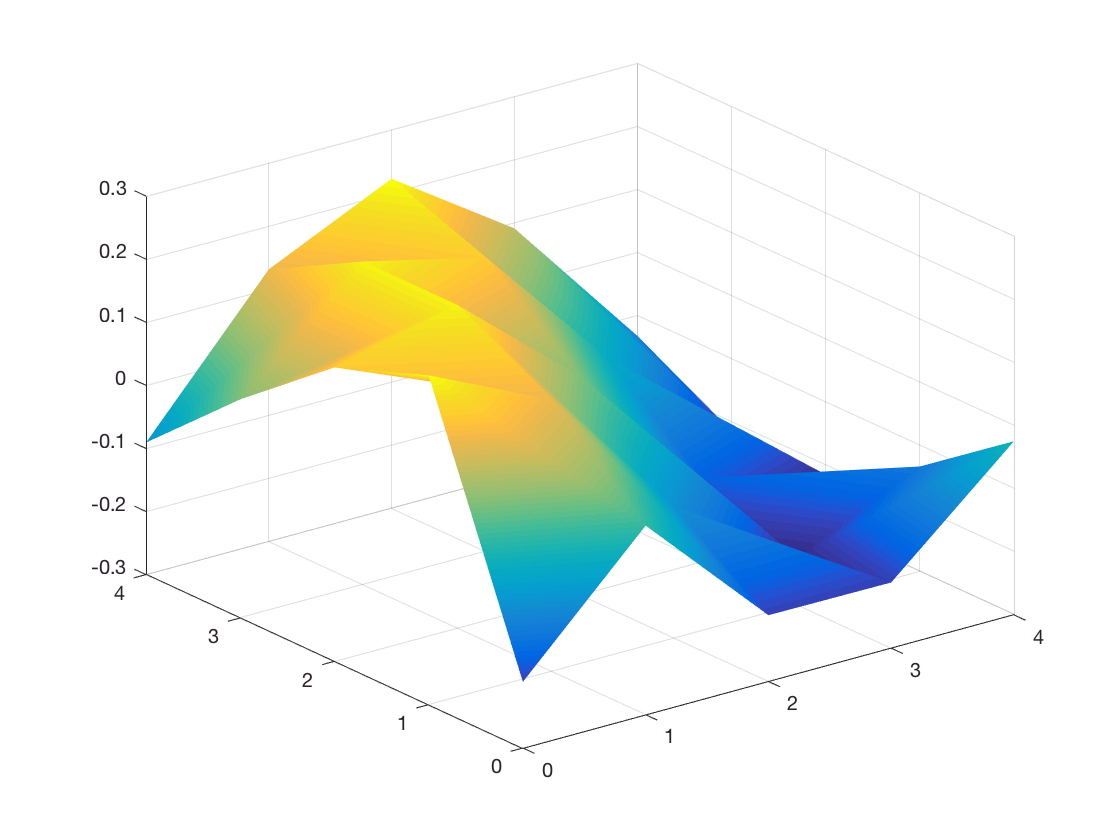

figure 
C_grid = reshape(f_r, [5,5]);
surf(X1, X2, C_grid,'LineStyle', 'none', 'FaceColor', 'interp')

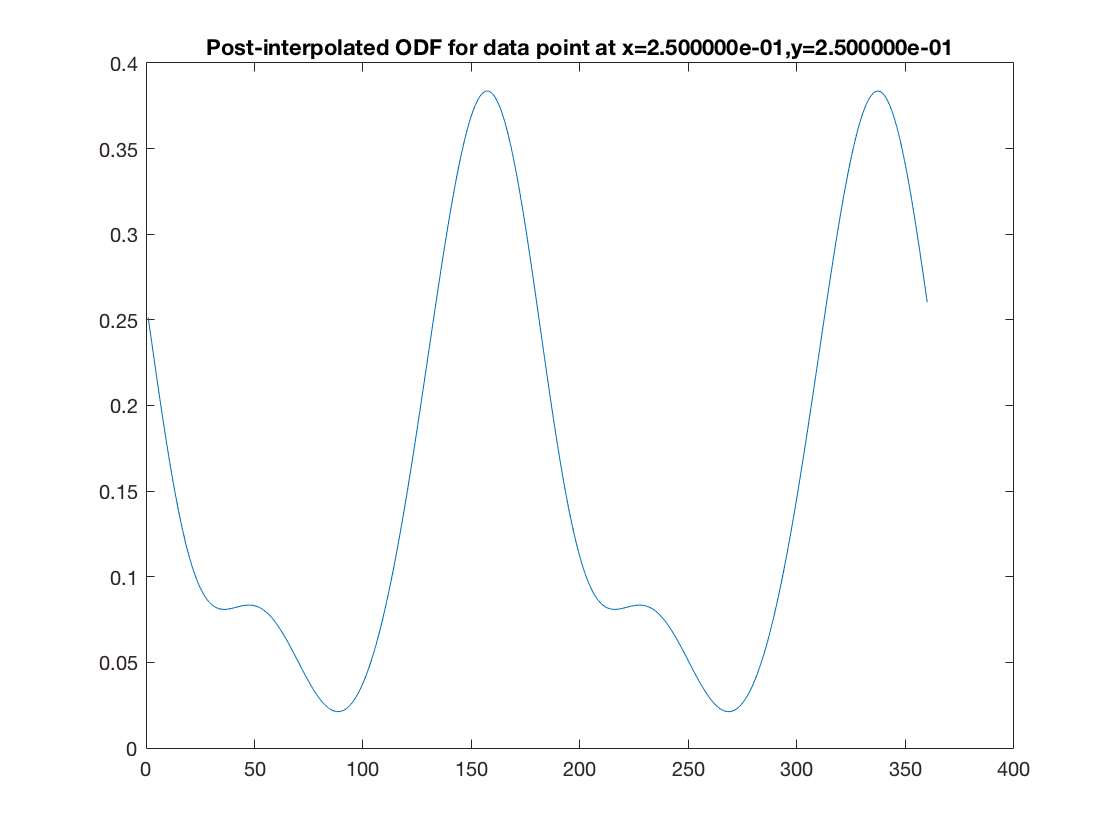


% Gen data from for plotting
d = evalFourier(an_prime, bn_prime, 1, 1:360);
figure
plot(d)
title(sprintf('Post-interpolated ODF for data point at x=%d,y=%d', x_prime, y_prime));

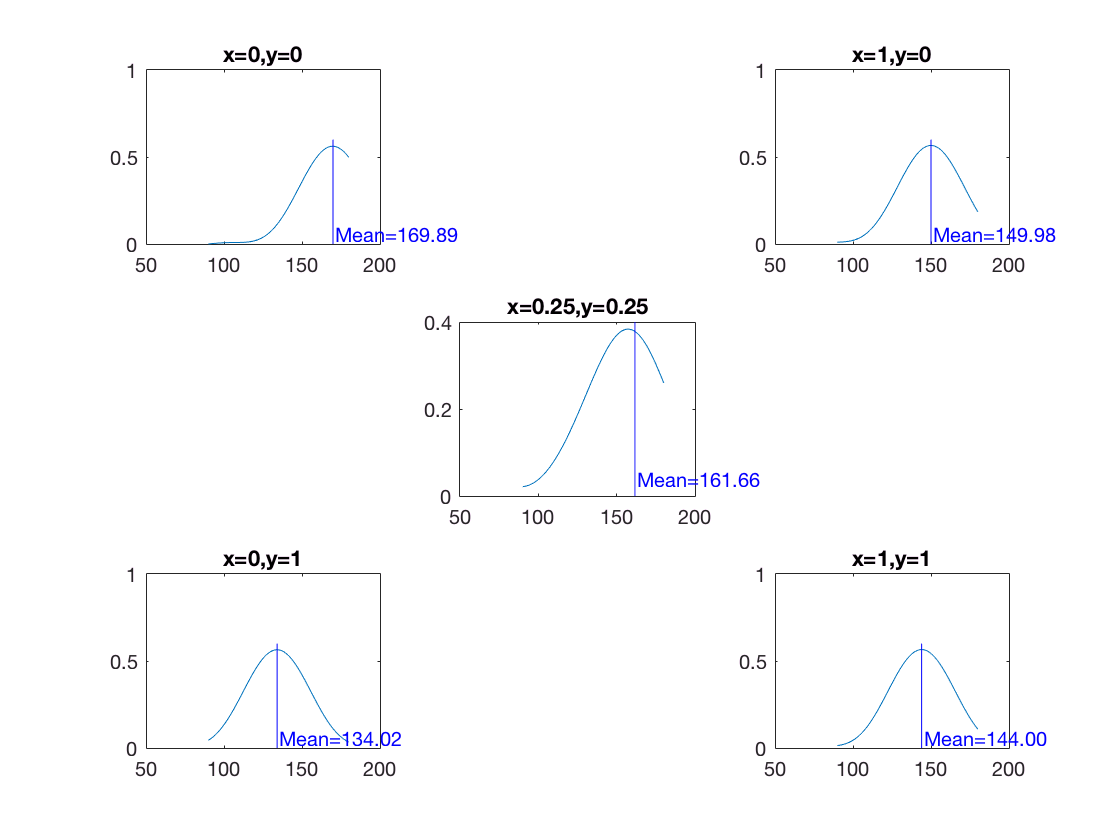


data_points2(1) = data_points2(1).ComputeStats;
theta1 = data_points2(1).mean_odf;
figure
subplot(3,3,1); plot(90:180, data_points2(1).odf(90:180)); title(sprintf('x=%d,y=%d', data_points2(1).x, data_points2(1).y));
vline(theta1*180/pi,'b', sprintf('Mean=%.2f',theta1*180/pi)); 

data_points2(2) = data_points2(2).ComputeStats;
theta1 = data_points2(2).mean_odf;
subplot(3,3,3); plot(90:180, data_points2(2).odf(90:180)); title(sprintf('x=%d,y=%d', data_points2(2).x, data_points2(2).y));
vline(theta1*180/pi,'b', sprintf('Mean=%.2f',theta1*180/pi)); 

data_points2(6) = data_points2(6).ComputeStats;
theta1 = data_points2(6).mean_odf;
subplot(3,3,7); plot(90:180, data_points2(6).odf(90:180)); title(sprintf('x=%d,y=%d', data_points2(6).x, data_points2(6).y));
vline(theta1*180/pi,'b', sprintf('Mean=%.2f',theta1*180/pi)); 

data_points2(7) = data_points2(7).ComputeStats;
theta1 = data_points2(7).mean_odf;
subplot(3,3,9); plot(90:180, data_points2(7).odf(90:180)); title(sprintf('x=%d,y=%d', data_points2(7).x, data_points2(7).y));
vline(theta1*180/pi,'b', sprintf('Mean=%.2f',theta1*180/pi)); 

theta1 = d_int.mean_odf;
subplot(3,3,5); plot(90:180, d(90:180));title(sprintf('x=%.2f,y=%.2f', x_prime, y_prime));
vline(theta1*180/pi,'b', sprintf('Mean=%.2f',theta1*180/pi)); 

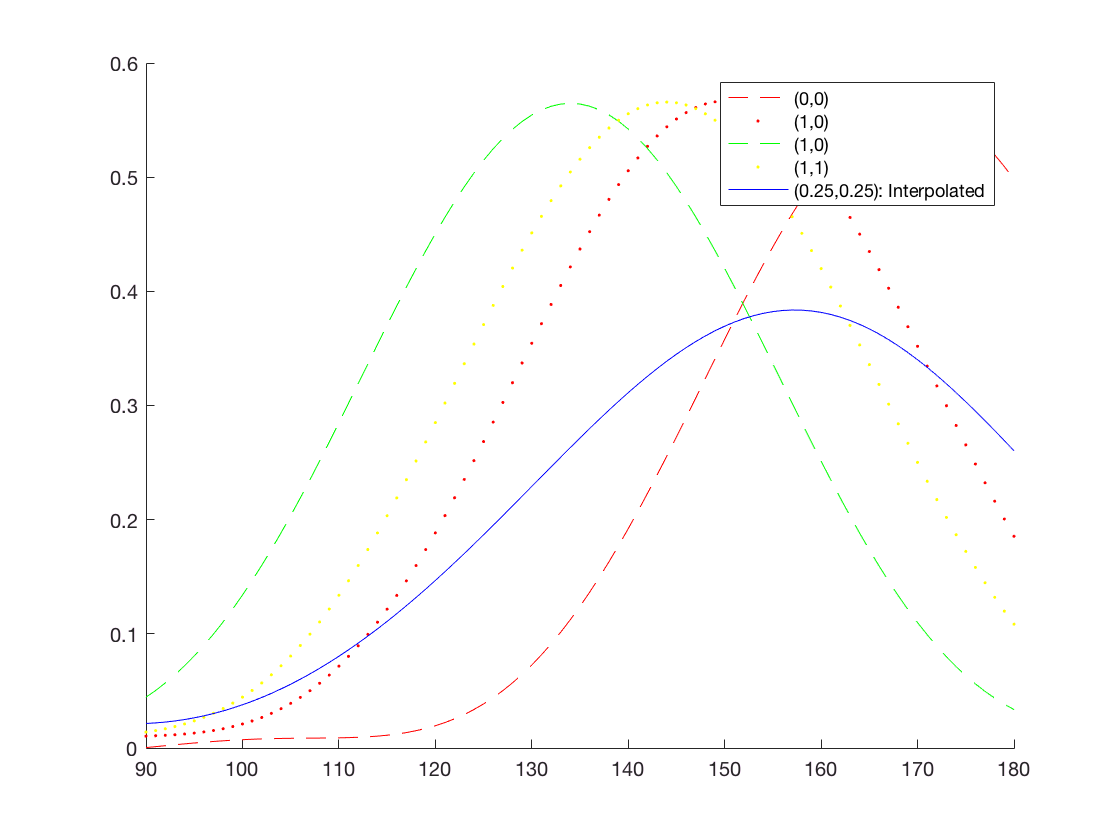



figure
hold on;
plot(90:180, data_points2(1).odf(90:180), 'r--'); 
% vline(data_points2(1).mean_odf*180/pi + 180,'r--'); 
plot(90:180, data_points2(2).odf(90:180), 'r.');
% vline(data_points2(2).mean_odf*180/pi+ 180,'r--'); 
plot(90:180, data_points2(6).odf(90:180),'g--');
% vline(data_points2(6).mean_odf*180/pi+ 180,'g--'); 
plot(90:180, data_points2(7).odf(90:180), 'y.'); 
% vline(data_points2(7).mean_odf*180/pi+ 180,'y--'); 
plot(90:180, d(90:180),'b');
% vline(d_int.mean_odf+ 180,'b'); 
legend('show','(0,0)','(1,0)','(1,0)','(1,1)', '(0.25,0.25): Interpolated')
hold off